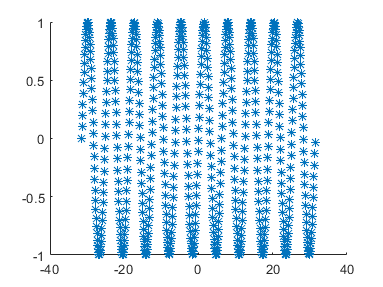

%% Movie Test.
 
%% Set up some function. 
% Sine between -2*pi and 2*pi.
x = (10*-pi:0.1:10*pi)'; % Note the transpose.
y = sin(x);
fid = figure;
hold on
% The final plot.
plot(x,y, '*');

 
%% Set up the movie.
writerObj = VideoWriter('out.avi'); % Name it.
writerObj.FrameRate = 60; % How many frames per second.
open(writerObj); 
 
for i=1:size(y)      
    % We just use pause but pretend you have some really complicated thing here...
    pause(0.1);
    figure(fid); % Makes sure you use your desired frame.
    plot(x(i),y(i),'or');
 
    %if mod(i,4)==0, % Uncomment to take 1 out of every 4 frames.
        frame = getframe(gcf); % 'gcf' can handle if you zoom in to take a movie.
        writeVideo(writerObj, frame);
    %end
 
end

Unrecognized function or variable 'fId'.

hold off
close(writerObj); % Saves the movie.